# **BPC-SAS Zaverecny projekt**

**Autor: Matyas Peroutik**

**VUT ID: 256371**

### **Úkol 1: **Analýza a číslicová filtrace signálu

V eLearningu máte dostupný audio soubor typu wav, pojmenovaný podle vašeho ID. Nahrávka obsahuje tři hlavní složky: užitečný signál (zvuk ptáčků), šum (zvuky větru a listí) a periodické rušení. K dispozici máte konečný úsek signálu. Předpokládejte, že se tento úsek neustále periodicky opakuje.

- Pomocí vhodné transformace zjistěte, jaké periodické rušení signál obsahuje. Do jednoho okna vykreslete dva grafy:

                        •  načtenou časovou řadu (tj., vzor signálu);

                        • transformovaný signál (tj., obraz signálu) — použijte logaritmické osy, vertikální i horizontální.

          2. Rušení odstraňte tím, že na obraz signálu aplikujete vhodné signálové manipulace. (Šum lesa odstraňovat nemusíte.) Pak obraz signálu převeďte zpět do časové oblasti. Upravený obraz i signál dokreslete do grafů z bodu 1.

#### Zpracovani:

Pred zacatkem zpracovani prvni ulohy vycistime pameti matlabu

clear;
clc;
close all;

Jako prvni si do matlabu nactu soubor s audiosouborem, ktery mam upravit. Nasta

filepath = "/home/neo/Documents/Projekty/BPC-SAS_final/peroutik_vut/BPC-SAS/256371.wav"

filepath = "/home/neo/Documents/Projekty/BPC-SAS_final/peroutik_vut/BPC-SAS/256371.wav"

[signal, sample_rate] = audioread(filepath);

Po nacteni signalu si nasledne muzeme zobrazit jeho prubeh. Casovove rozpeti muzeme vypocitat tak, ze pocet vzorku vynasobime vzorkovaci frekvenci. Pote udelame vektor obsahujici casove body zisku signalu. Proto nejprve musime ziskat tyto udaje z naseho signalu.

signal_size       = size(signal);
sample_period     = 1/sample_rate

sample_period = 2.2676e-05

signal_end_time   = signal_size(1)*sample_period;
signal_timestamps = 0:(sample_period):signal_end_time-sample_period;

Nasledne muzeme sestavit graf. Graf se zobrazi ve figure 1 v horni casti.

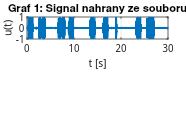

figure(1);

subplot(2,1,1);   % Graf 1 v prvnim poli FIG1
plot(signal_timestamps,signal);

% Uprava stylu grafu
xlim([0 30]);   % Rozsah X
grid on;        % Zapnuti gridu
title("Graf 1: Signal nahrany ze souboru")
xlabel("t [s]");
ylabel("u(t)");